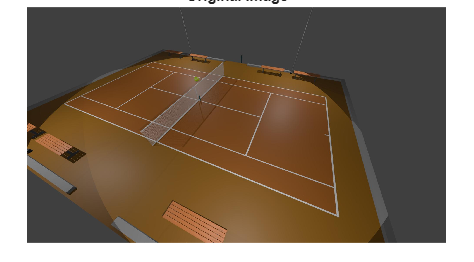

imagePath = "captures\leftImg_1.jpeg";

% Read image
img = imread(imagePath);
figure; imshow(img); title('Original Image');

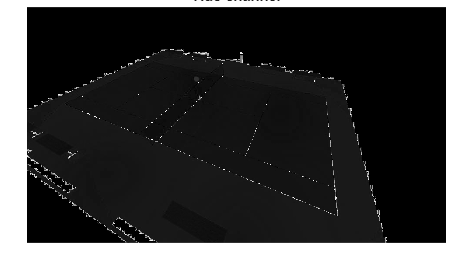


% Convert to HSV
hsvImg = rgb2hsv(img);
H = hsvImg(:, :, 1);
S = hsvImg(:, :, 2);
V = hsvImg(:, :, 3);

figure; imshow(H); title('Hue channel');

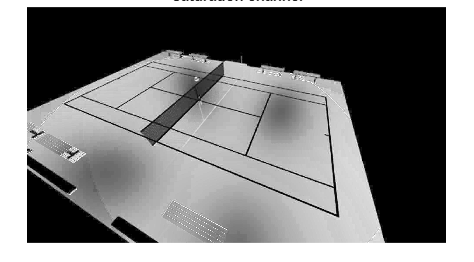

figure; imshow(S); title('Saturation channel');

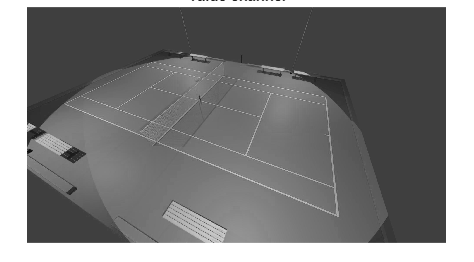

figure; imshow(V); title('Value channel');

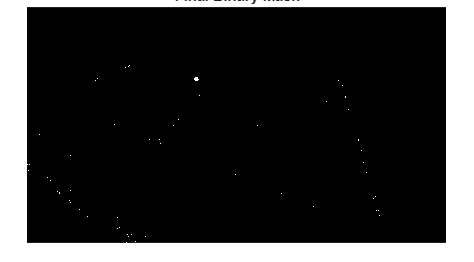


% Thresholds
hueMask = (H > 0.18 & H < 0.22);
satMask = (S > 0 & S < 1);
valMask = (V > 0 & V < 1);

% Final binary mask
finalMask = hueMask & satMask & valMask;

figure; imshow(finalMask); title('Final Binary Mask');

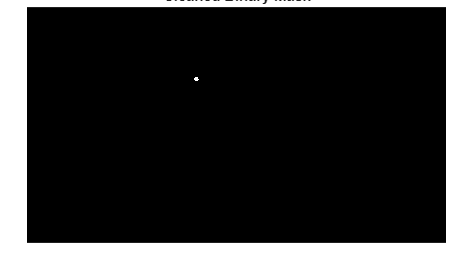


% Optional cleanup
finalMask = bwareaopen(finalMask, 50);     % remove tiny noise
finalMask = imfill(finalMask, 'holes');    % fill holes

figure; imshow(finalMask); title('Cleaned Binary Mask');

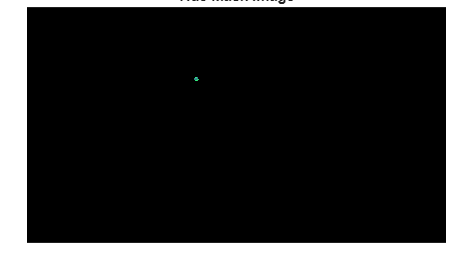


% Create masked HSV image just for visualization
hueMaskImg = hsvImg;
hueMaskImg(repmat(~finalMask, [1 1 3])) = 0;
figure; imshow(hueMaskImg); title('Hue Mask Image');

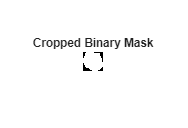

imwrite(hueMaskImg,'identifiedBall.jpg','jpg');

%% REGION BOUNDING
% This region bounding works by finding a non zero object in the image
% because I have used HSV to find just the ball and cut out everything else
% with a narrow HSV mask, the only non zero (non-black value) is the ball
% this makes region cropping very easy

[rows, cols] = size(finalMask);

% Top-down cut
topRow = find(any(finalMask, 2), 1, 'first');

% Bottom-up cut
bottomRow = find(any(finalMask, 2), 1, 'last');

% Left-to-right cut
leftCol = find(any(finalMask, 1), 1, 'first');

% Right-to-left cut
rightCol = find(any(finalMask, 1), 1, 'last');

% Check if any object was found
if isempty(topRow) || isempty(bottomRow) || isempty(leftCol) || isempty(rightCol)
    error('No valid region found in the mask.');
end

% Crop mask and original image
croppedMask = finalMask(topRow:bottomRow, leftCol:rightCol);
croppedImg  = img(topRow:bottomRow, leftCol:rightCol, :);

figure; imshow(croppedMask); title('Cropped Binary Mask');

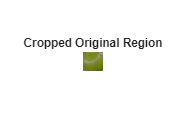

figure; imshow(croppedImg); title('Cropped Original Region');


stats = regionprops(croppedMask, ...
    'Area', 'BoundingBox', 'Centroid', 'MajorAxisLength', ...
    'MinorAxisLength', 'Eccentricity');

% Display results
disp('Region Properties:');

Region Properties:


disp(stats);

               Area: 301
           Centroid: [10.5847 9.7907]
        BoundingBox: [0.5000 0.5000 20 19]
    MajorAxisLength: 21.4739
    MinorAxisLength: 18.0366
       Eccentricity: 0.5427



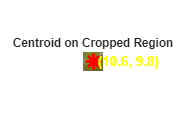


figure; imshow(croppedImg); title('Centroid on Cropped Region');
hold on;

for k = 1:length(stats)
    c = stats(k).Centroid;
    plot(c(1), c(2), 'r*', 'MarkerSize', 12, 'LineWidth', 2);
    text(c(1)+5, c(2), sprintf('(%0.1f, %0.1f)', c(1), c(2)), ...
        'Color', 'yellow', 'FontSize', 10, 'FontWeight', 'bold');
end

hold off;

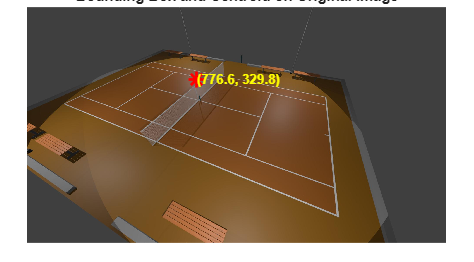


figure; imshow(img); title('Bounding Box and Centroid on Original Image');
hold on;

% Bounding box on original image
rectangle('Position', [leftCol, topRow, rightCol-leftCol+1, bottomRow-topRow+1], ...
          'EdgeColor', 'g', 'LineWidth', 2);

% Centroid mapped back to original image coordinates
for k = 1:length(stats)
    c = stats(k).Centroid;
    globalX = c(1) + leftCol - 1;
    globalY = c(2) + topRow - 1;

    plot(globalX, globalY, 'r*', 'MarkerSize', 12, 'LineWidth', 2);
    text(globalX+5, globalY, sprintf('(%0.1f, %0.1f)', globalX, globalY), ...
        'Color', 'yellow', 'FontSize', 10, 'FontWeight', 'bold');
end

hold off;